% matrix must be positive definite
A = [2 -1 0 ;
     -1 2 -1 ;
     0 -1 2 ;]

A =      2    -1     0
    -1     2    -1
     0    -1     2



AC = [ 1 2 1; 
       2 5 2; 
       1 2 1];

b = [1;1;1];

% matrix must be positive definite

check = MatrixChecks;
check.A = A;
check.b = b;

c = T_Cholesky;
c.A = A;

[L, R] = c.cholesky

start cholesky decomposition
start calcualte eigenvalues
Elapsed time is 0.000031 seconds.
the matrix is positive definite
Elapsed time is 0.000140 seconds.


L =    1.414213562373095                   0                   0
  -0.707106781186547   1.224744871391589                   0
                   0  -0.816496580927726   1.154700538379251


R =    1.414213562373095  -0.707106781186547                   0
                   0   1.224744871391589  -0.816496580927726
                   0                   0   1.154700538379251



L * R

ans =    2.000000000000000  -1.000000000000000                   0
  -1.000000000000000   2.000000000000000  -1.000000000000000
                   0  -1.000000000000000   2.000000000000000


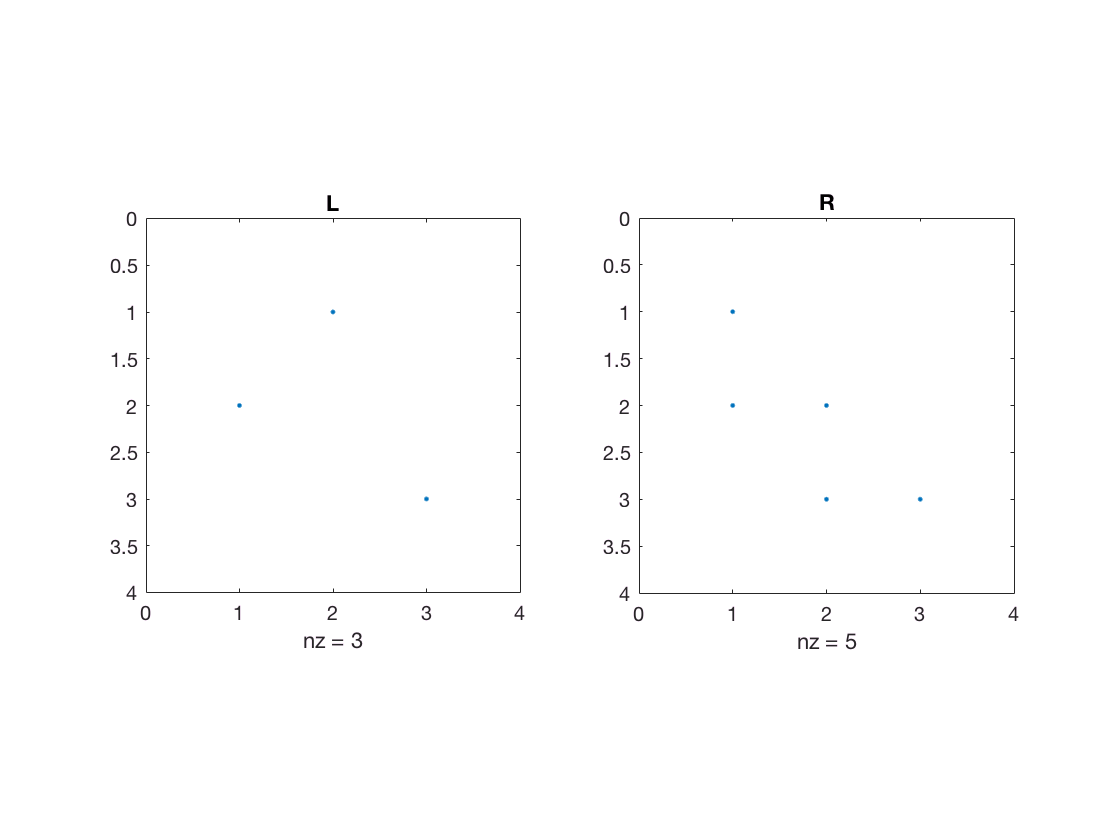


subplot(1, 2, 1)
spy(P), title('L')
subplot(1, 2, 2)
spy(L), title('R')